# Computer Assignment #1 

# Fourier Analysis 

# Ali Hamzehpour 810100129

## Part 1 Matlab Basics

### 1.1 Plotting functions

#### 
$$y = cos(\frac{\pi t}{4})sin(\frac{\pi t}{8})$$
 

For plotting functions, first we have to define a vector for the domain of the functions(variable t in the code) and then we define another vector which using the formula of the function and the domain vector. Then we plot it.

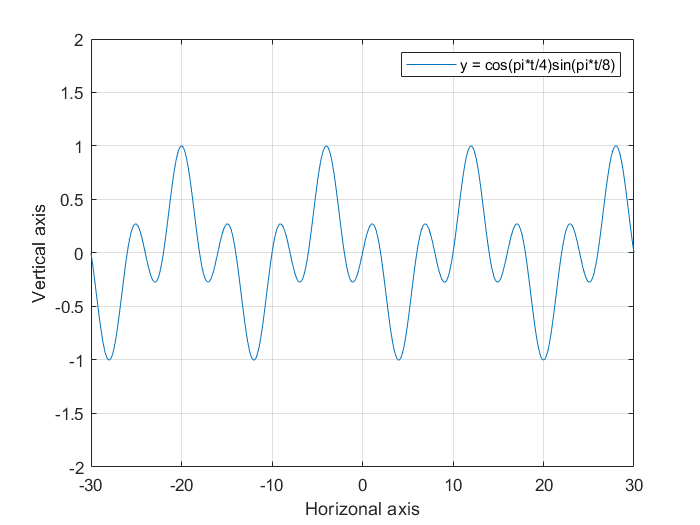

MIN_T = -30;
MAX_T = 30;
t = linspace(MIN_T, MAX_T, 1000);
x = cos(pi*t/4) .* sin(pi*t/8);
plot(t, x)
xlabel("Horizonal axis");
ylabel("Vertical axis");
ylim([-2 2]);
xlim([MIN_T MAX_T]);
legend("y = cos(pi*t/4)sin(pi*t/8)")
grid on;

#### 
$$y = (t+1)sin(\frac{1}{t})
$$


Plotting this function is the same as the previous function. The difference is when $t$ is near 0, function's values change dramatically so to show that, I increased the sample frequency.

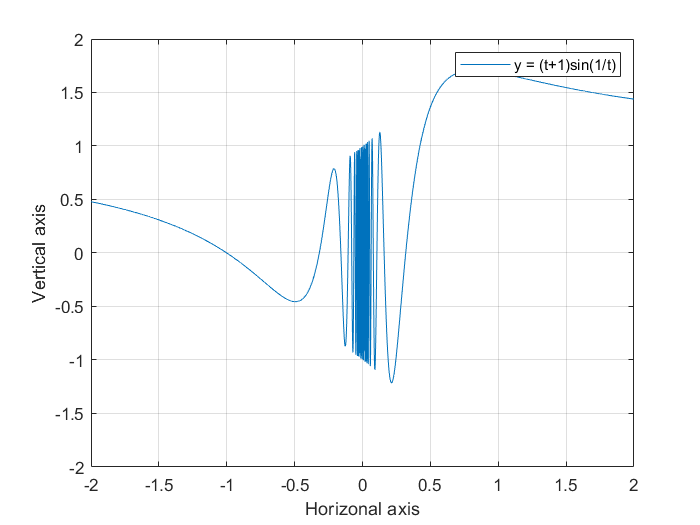

MIN_T = -2;
MAX_T = 2;
t = linspace(MIN_T, MAX_T, 10000);
x = (t+1) .* sin(1 ./ t);
plot(t, x)
xlabel("Horizonal axis");
ylabel("Vertical axis");
ylim([-2 2]);
xlim([MIN_T MAX_T]);
legend("y = (t+1)sin(1/t)")
grid on;

#### 
$$\[
y =
\begin{cases}
-1 & \text t \lt -3\\
ramp(t) & \text{-3 < t < 3}\\
e^{-3t} & \text{ t > 3}
\end{cases}
\]$$


In order to plot a piecewise function, I defined each part of the function seperately and then merged them together. In the plot $e^{-3t}$ seems like it's a straight line at 0 because the its values are so close to 0.

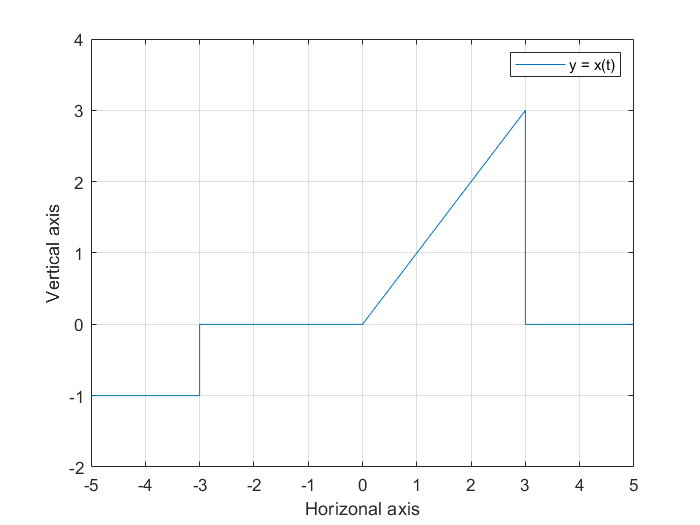

MIN_T = -5;
MAX_T = 5;
t1 = linspace(MIN_T, -3, 1000);
x1 = t1 ./ -t1;
t2 = linspace(-3, 3, 1000);
x2 = max(0, t2);
t3 = linspace(3, MAX_T, 1000);
x3 = exp(-3 * t3);
t = [t1 t2 t3];
x = [x1 x2 x3];
plot(t, x)
xlabel("Horizonal axis");
ylabel("Vertical axis");
ylim([-2 4]);
xlim([MIN_T MAX_T]);
legend("y = x(t)")
grid on;

## Part 2. Fourier Series

### 2.1 Calculating the fourier series of f(x) = $x^\alpha$

The code of this part is in the end of the file becuase it's a function(functions in Matlab should be at the bottom of the file)

*calc_fourier_serues* gets 4 parameters(Num, P, alpha, Nshow) and show the fourier series of $x^\alpha$(until n = Nshow)  and plot it(until n = Num and p is number of periods we have to show).

I defined a(n) and b(n) which are the coefficients of the fourier series as a symbolic variable and with a for loop, I calculated the whole series.

### 2.2 Calculating the Fourier series of f(x) = $x^2
$

In this part we simply call the function we wrote in the previous part.(Num = 10, Nshow = 5, p = 3)

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

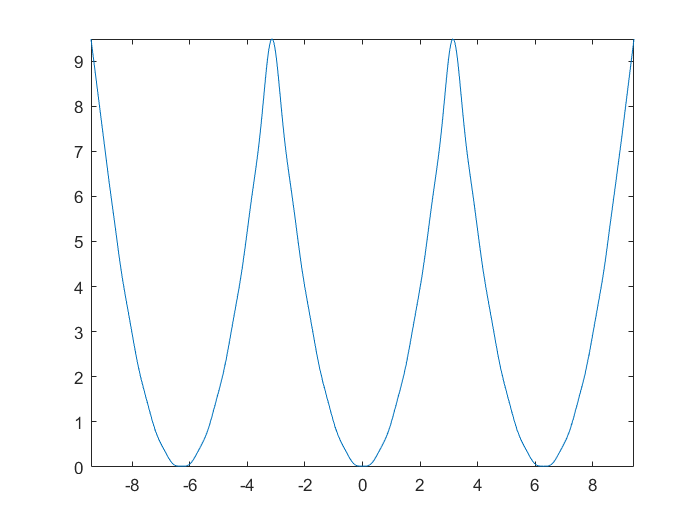

calc_fourier_series(10, 3, 2, 5);

### 2.3 Plotting Fourier Series with Different Nums and Comparison

In this part I plotted $y = x^2$ with Num = 1, 10, 50 and 100. For Num = 10, 50, 100 The plots are in general so smiliar. In general the bigger Num the closer our plot will be with the original function. 

calc_fourier_series(1, 3, 2, 5);

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

hold on;
calc_fourier_series(10, 3, 2, 5);

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

hold on;
calc_fourier_series(50, 3, 2, 5);

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

calc_fourier_series(100, 3, 2, 5);

$$to\_show(x) = \cos\left(2\,x\right)-\frac{4\,\cos\left(3\,x\right)}{9}+\frac{\cos\left(4\,x\right)}{4}-\frac{4\,\cos\left(5\,x\right)}{25}-4\,\cos\left(x\right)+\frac{\pi^{2}}{3}$$

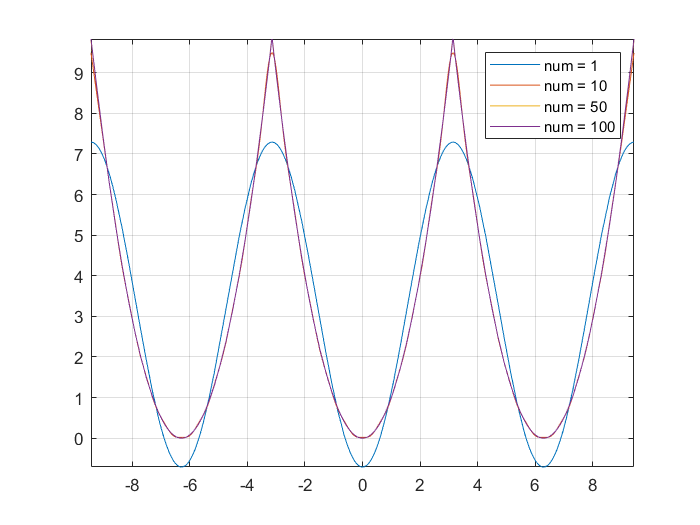

legend("num = 1", "num = 10", "num = 50", "num = 100");
grid on;
hold off;

### 2.4 Calculating the limit of a series' sum

We want to find the Fourier series of $x^2$ on the interval $[-\pi, \pi]$. Since $x^2$ is an even function, its Fourier series will only have cosine terms. Therefore, we can write:


$$\[
x^2 = \frac{a_0}{2} + \sum_{n=1}^{\infty} a_n \cos(nx)
\]$$



$$\[
a_0 = \frac{1}{2\pi} \int_{-\pi}^{\pi} x^2 dx = \frac{\pi^2}{3}
\]
$$



$$\[
a_n = \frac{1}{\pi} \int_{-\pi}^{\pi} x^2 \cos(nx) dx = \frac{4}{\pi} \int_{0}^{\pi} x^2 \cos(nx) dx
\]$$


and


$$
\int x^2 \cos(nx) dx = \frac{x^2}{n} \sin(nx) - \frac{2}{n} \int x \sin(nx) dx 
= \frac{x^2}{n} \sin(nx) + \frac{2}{n^2} \cos(nx) - \frac{2x}{n^2} \cos(nx) 
= \frac{x^2}{n} \sin(nx) - \frac{2}{n^3} \sin(nx) - \frac{2}{n^2} x \cos(nx)
$$


so


$$a_n = \frac{2}{\pi} \int_{0}^{\pi} x^2 \cos(nx) dx 
= \frac{2}{\pi} \left[ \frac{x^2}{n} \sin(nx) - \frac{2}{n^2} \sin(nx) - \frac{2}{n^2} x \cos(nx) \right]_{0}^{\pi} 
= \frac{4}{n^2} (-1)^n$$
    


$$\[
x^2 = \frac{\pi^2}{3} + \sum_{n=1}^{\infty} \frac{4}{n^2} (-1)^n \cos(nx)
\]$$


Now we have to show$\sum_{n=1}^{\infty} \frac{1}{n^2} 
= \frac{\pi^2}{6}$. we set $x = \pi:$


$$\pi^2= \frac{\pi^2}{3} + 4\sum_{n=1}^{\infty} \frac{1}{n^2} $$


so


$$ \sum_{n=1}^{\infty} \frac{1}{n^2} = \frac{\pi^2}{6}  $$


Now in code we calculate the value of fourier series function with x = $\pi$ and calculate the difference of the result 

with $\frac{\pi^2}{6}$ and as we see the difference is so low and they're approximately equal.

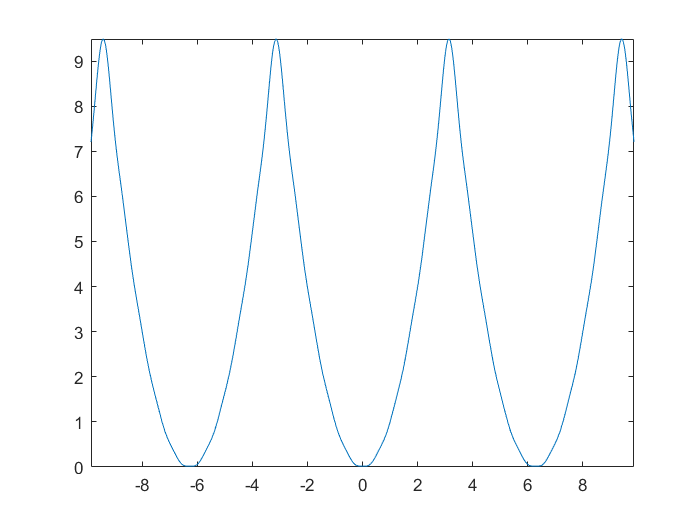

[to_show] = calc_fourier_series(10, pi, 2, 100);

syms x;
sigma(x) = (to_show(x) - pi^2/3) / 4;
difference = vpa(sigma(pi) - pi^2/6, 5);
fprintf("The difference between pi^2/6 and the approximate sum: %f", difference);

The difference between pi^2/6 and the approximate sum: -0.009950

### 2.5 Harmonic Analysis in Fourier Series

Harmonic Analysis is the procedure of finding Fourier Series coefficients using numerical values:


$$f(x)= \frac{A_0}{2}+ \sum_{n=1}^{\infty}{A_ncos(nx)+B_nSin(nx)} \\
A_0 = 2 \frac{\sum f(x)}{numOfSamples}, 
A_n = 2 \frac{\sum f(x)cos(nx)}{n},
B_n = 2 \frac{\sum f(x)sin(nx)}{n}


$$


#### 2.5.1 Harmonic Analysis Simulation

This part is at the end of the file too. I wrote a function(calc_first_n_harmonic) that gets values of x ,f(x) and n, calculates the first n harmonics of Fourier Series and plot it. The function first calculates coeffiecients and then calculates the harmnic function with the formula above.

With given table I called the function:

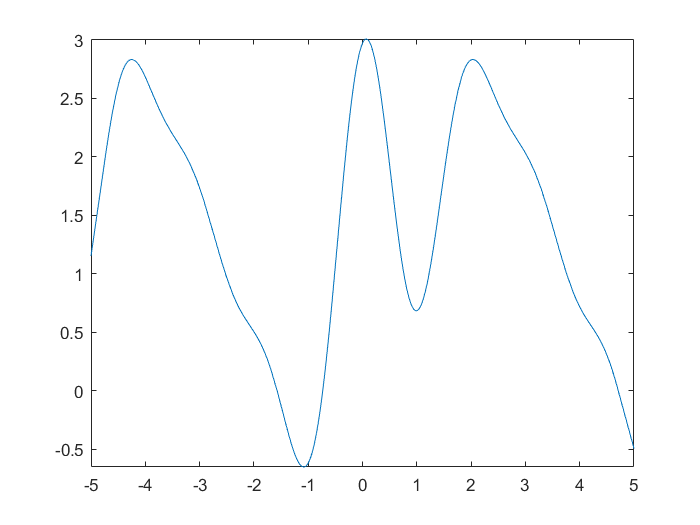

$$fourier\_func = 0.7\,\cos\left(2.0\,x\right)+0.35\,\cos\left(4.0\,x\right)-0.17321\,\sin\left(2.0\,x\right)+0.086603\,\sin\left(4.0\,x\right)+0.73333\,\cos\left(3.0\,x\right)-2.6942e-16\,\sin\left(3.0\,x\right)-0.2\,\cos\left(x\right)+1.0392\,\sin\left(x\right)+1.3857$$

xs = [0 pi/3 2*pi/3 pi 4*pi/3 5*pi/3 2*pi];
fx = [1 1.4 1.9 1.7 1.5 1.2 1];
calc_first_n_harmonic(xs, fx, 4);

## Part 3 Fourier Transform

### 3.1 Sampling Frequency

Sampling frequency is the number of samples taken per second when converting an analog signal to a digital signal. It is a measure of how often the signal is measured or sampled. The higher the sampling frequency, the more accurately the original analog signal can be reconstructed from the digital signal.


$$Sampling \ Frequency = \frac{1}{Sampling \ Rate}
$$


### 3.2 Checking some functions in terms of time and frequency

I wrote a function called "plot_and_fft" which gets a function and plot it and then calculates its Fourier Transform and plots it too. I used fft and fftshift functions to calculate the Fourier Transform.

*Why should we use fftshift?*

when you use fft the array will be:

0 1 2 3 ... Fs/2   -Fs/2 ... -3 -2 -1

<----------------> <------------------>

  positive freq        negative freq

by using fftshift zero frequncy is shifted to center of array so we have:

 -Fs/2 ... -3 -2 -1   0 1 2 3 ... Fs/2

<------------------> <---------------->

    negative freq      positive freq

### 
$$y = cos(\pi t)$$


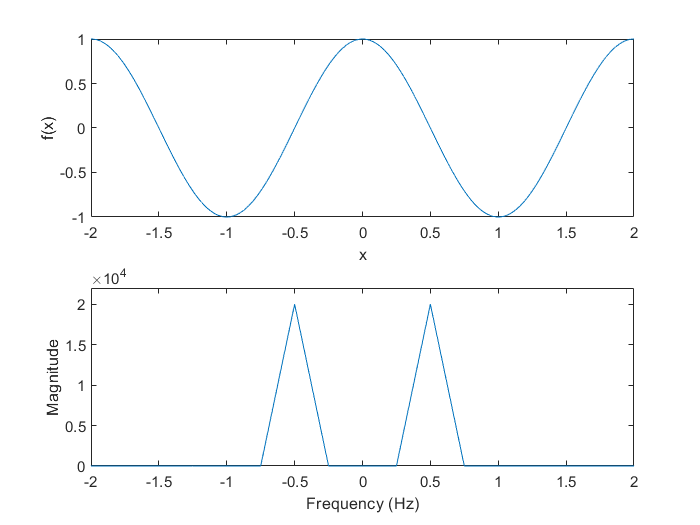

f = @(x) cos(pi*x);
plot_and_fft(f, -2, 2, 10000);

The output is two delta dirac at -0.5 and 0.5.(the reason that it's like a triangle is we worked with discrete points so the plot looks like a triangle) and theoretically.:


$$F(\omega) = \int_{-\infty}^{\infty} \cos(\pi t) e^{-j\omega t} dt$$



$$\Longrightarrow F(\omega) = \int_{-\infty}^{\infty} \frac{1}{2} \left( e^{j\pi t} + e^{-j\pi t} \right) e^{-j\omega t} dt$$



$$ \Longrightarrow F(\omega) = \frac{1}{2} \int_{-\infty}^{\infty} e^{j(\pi - \omega)t} + e^{-j(\pi + \omega)t} dt$$



$$\Longrightarrow F(\omega) = \pi \left( \delta(\omega - \pi) + \delta(\omega + \pi) \right)$$


which in terms of frequency is:


$$F(f) = \pi \left( \delta(f - \frac{1}{2}) + \delta(f + \frac{1}{2}) \right)
$$


which is like what our function found.

### 
$$y = 1$$


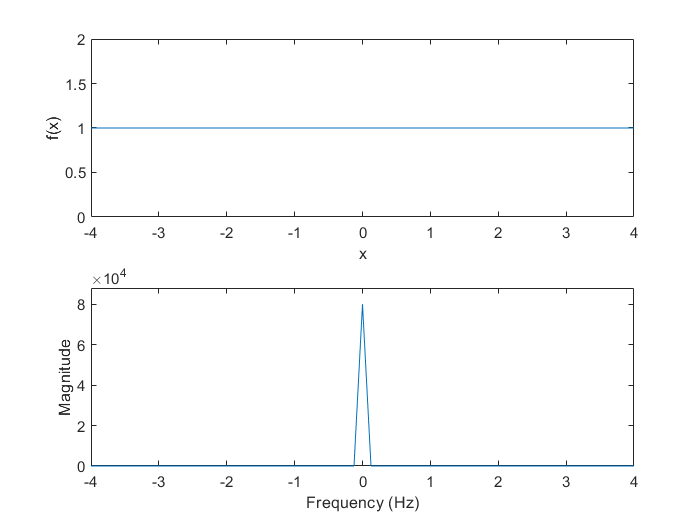

f = @(x) x - x + 1;
plot_and_fft(f, -4, 4, 10000);

The transform of the function is an impulse on f = 0 and theoretically:


$$F(f) = \int_{-\infty}^{\infty} 1 \cdot e^{-2\pi i f t} dt =  2\pi\delta(f)$$


which is the same as what our function calculated.

### 
$$y = \delta(t)$$


I defined dirac function as min(1, $\delta(t)$) because the dirac function in matlab gets infinite value at 0 and the function didn't work properly with that. With this implemetation f(t) = 0 every but in t = 0. in t = 0 f(t) is 1.

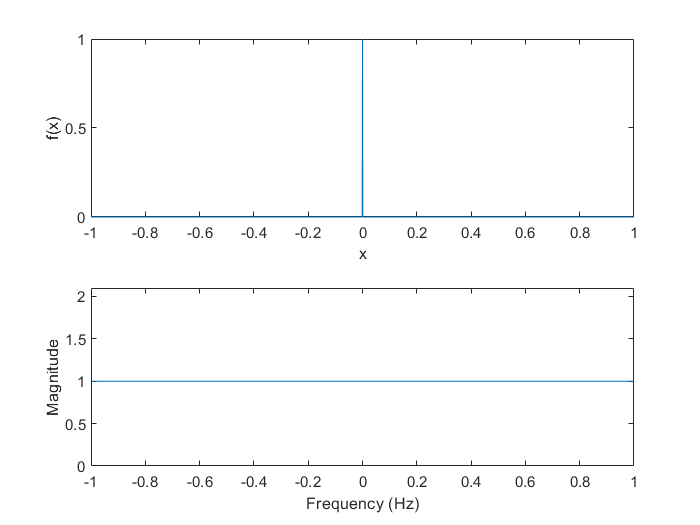

f = @(x) min(1, dirac(x));
plot_and_fft(f, -1, 1, 1000);

according to our function Fourier transform of dirac function is a constant(y = 1) and on paper:


$$F(f) = \int_{-\infty}^{\infty} \delta(t) \cdot e^{-2\pi i f t} dt = e^{-2\pi i f \times 0} = 1$$


which is the same as what our function calculated.

### 3.3 Music

In this part we are given a music file and we have to play it in Matlab, check its sampling frequency and half it to see how it changes.

First we read the file, listen to it and check its sampling frequency:

filename = 'ABITW.mp3';
[x, Fs] = audioread(filename);
display(Fs)

Fs = 44100

The Nyquist-Shannon theorem says in order to accurately reconstruct a continuous-time signal from its discrete-time samples, the sampling frequency must be at least twice the highest frequency component in the signal so the Fs in output should be that high.

sound(x, Fs);
pause(length(x)/Fs);
clear sound;

for the next part we save the file with twice the frequency rate we got from audioread

Fs_double = Fs*2;
audiowrite('ABITWDouble.wav', x, Fs_double)

If we play a sound with a sampling rate that is twice the original sampling frequency, the sound will be played back at twice the speed and the pitch of the sound will be higher. This is because the sampling frequency determines the number of samples per second that are used to represent the audio signal.

for the next part we save the file with half the frequency rate we got from audioread

Fs_half = Fs/2;
audiowrite('ABITWHalf.wav', x, Fs_half)

If we lower the frequency we might go below the minimun frequency stated in The Nyquist-Shannon theorem we might lose some high frequency content in our audio signal. Also If we play a sound with a sampling rate that is half the original sampling frequency, the sound will be played back at half the speed and pitch of the sound will get lower too.

### Functions

function [to_show] = calc_fourier_series(num, p, alpha, nshow)
    syms x;
    y = x ^ alpha;
    syms n;
    l = pi;
    a_0 = int(y, x, -l, l) / l;
    a_n(n) = int(y * cos((n*pi/l) * x), x, -l, l) / l;
    b_n(n) = int(y * sin((n*pi/l) * x), x, -l, l) / l;
    to_show(x) = a_0 / 2;
    to_plot(x) = a_0 / 2;
    for i=1:nshow
       to_show = to_show + a_n(i) * cos((i*pi/l) * x) + b_n(i) * sin((i*pi/l) * x); 
    end
    for i=1:num
       to_plot = to_plot + a_n(i) * cos((i*pi/l) * x) + b_n(i) * sin((i*pi/l) * x); 
    end
    display(to_show);
    fplot(to_plot);
    xlim([-p*pi, p*pi]);
end

function calc_first_n_harmonic(xs, fx, n)
    a = zeros(1, n);
    b = zeros(1, n);
    input_shape = size(xs);
    num_of_samples = input_shape(2);
    a_0 = 2 * sum(fx) / num_of_samples;
    for i=1:n
        for j=1:num_of_samples
            a(i) = a(i) + fx(j) * cos(i*xs(j)); 
            b(i) = b(i) + fx(j) * sin(i*xs(j)); 
        end
        a(i) = 2 * a(i) / i;
        b(i) = 2 * b(i) / i;
    end
    syms x;
    fourier_func = a_0 / 2;
    for i=1:n
        fourier_func = fourier_func + a(i) * cos(i*x) + b(i) * sin(i*x);
    end
    fourier_func = vpa(fourier_func, 5);
    fplot(fourier_func);
    display(fourier_func);
end

function plot_and_fft(f, x_min, x_max, fs)
    %x = linspace(x_min, x_max, fs * (x_max - x_min));
    x = x_min:1/fs:x_max;
    y = f(x);
    subplot(2,1,1);
    plot(x, y);
    xlabel('x');
    ylabel('f(x)');
    F = fft(y);
    F = fftshift(F);
    N = length(x); 
    freq = (-N/2:N/2-1)*fs/N;
    subplot(2,1,2);
    plot(freq, abs(F));
    f_max = max(abs(y));
    F_max = max(abs(F));
    xlim([x_min, x_max]);
    ylim([0, max([f_max, F_max])*1.1 + 1]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
end